# CLASE >> Transformada de Laplace

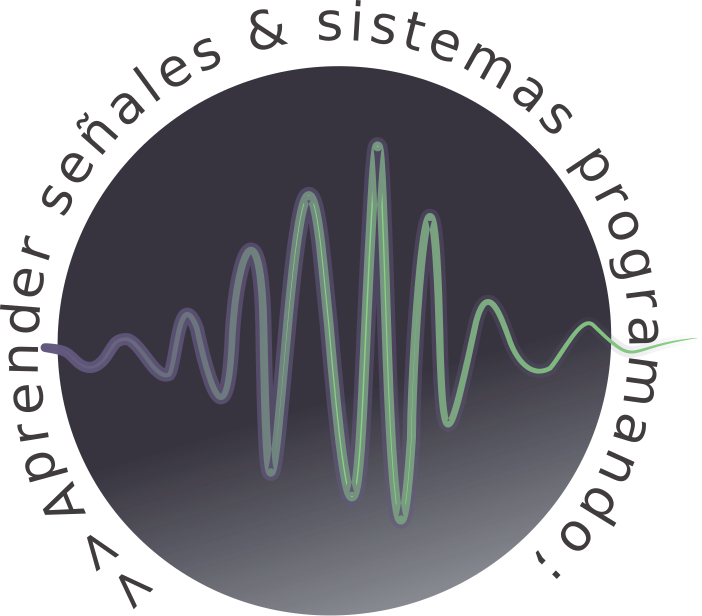

# Temario

- Introducción

- Primeras definiciones

- Propiedades

- Transformada racional

- Relación entre la apariencia de una señal y sus polos

- Transformadas con exponenciales

- Transformada de ecuaciones diferenciales con entrada y salida

- Ejemplos: Circuito RC y Sistema masa-resorte-amortiguador

# Introducción

La transformada de Laplace es un operador para señales de tiempo continuo; la misma es una generalización de la transformada de Fourier ya que surge de agregar un factor exponencial en el integrando de la definición de esta última.  

Este operador es muy útil para caracterizar los sistemas de tiempo continuo causales, lineales e invariantes en el tiempo; la relación entre las transformadas de Laplace de las señales de salida y de entrada de un sistema LTI se denomina **función de transferencia** y otorga, mediante una relación algebraica, la posibilidad de conocer la respuesta al impulso del mismo. 

# Primeras definiciones

Cuando se definió a la transformada de Fourier, se estableció que algunas señales reales no tenían transformada en el sentido ordinario sino que debía asignárseles una transformada de Fourier generalizada; veamos con un poquito más de profundidad de qué manera es que se salvan estas situaciones de no existencia de la transformada de Fourier.

Una de las señales de tiempo continuo a la cual no puede definírsele su transformada de Fourier es el escalón unitario u(t). La definición de la transformada de Fourier implica:

Sin embargo, **esta integral no existe**. Al agregarle un factor de convergencia, la expresión de arriba queda de la siguiente manera:

Esta integral va a converger, pero sólo en el caso en el cual σ > 0. La expresión de arriba, para ese caso, queda de la siguiente manera:

Llamando s = σ + jω:

Esta expresión es la **transformada de Laplace** de la señal de tiempo continuo escalón unitario. Es importante tener en cuenta que la misma está definida solamente para aquellos números complejos con parte real positiva; este grupo de números para los cuales está definida la transformada se llama **región de convergencia**. 

De manera general, entonces, se define a la transformada de Laplace **bilateral** de una señal continua x(t) como:

También puede definirse la transformada de Laplace **unilateral**, que es la que se termina utilizando para señales de tiempo continuo causales:

Al conjunto de números del plano s para los cuales converge esta integral se la denomina, como se estableció anteriormente, región de convergencia de la transformada de Laplace X(s) de x(t).  

En el desarrollo del curso, se trabajará exclusivamente con esta última transformada (se obviará el hecho de llamarla unilateral y se dará por sentado que se habla de esta última). Como en el caso de la transformada de Fourier, en el curso se denota a las señales temporales con letras minúsculas y a sus transformadas con letras mayúsculas.

## Ejemplo 1

Se procede a realizar la obtención de la transformada de Laplace de la función exponencial real causal:

El número b pertenece al conjunto de los reales.

Por definición, la transformada de Laplace de  x(t) es:

Siguiendo el desarrollo hecho en el pizarrón, se obtiene la siguiente expresión de la transformada de Laplace:

Con región de convergencia:

Como ya se ha visto en los apuntes de la serie y de la transformada de Fourier, puede hallarse fácilmente la expresión de la transformada de Laplace de una señal de tiempo continuo haciendo uso de **Symbolic** **Math** **ToolBox** en Matlab.

A continuación, se busca la expresión de la transformada de Laplace de la señal exponencial:

syms x b t 

x = exp(-b*t); 


$$x1 = \cos\left(t\right)+\sin\left(t\right)$$

XXX

$$x2 = \cos\left(t\right)+2\,\sin\left(t\right)$$

Ahora, se busca la expresión de la transformada de Laplace de la señal escalón unitario:

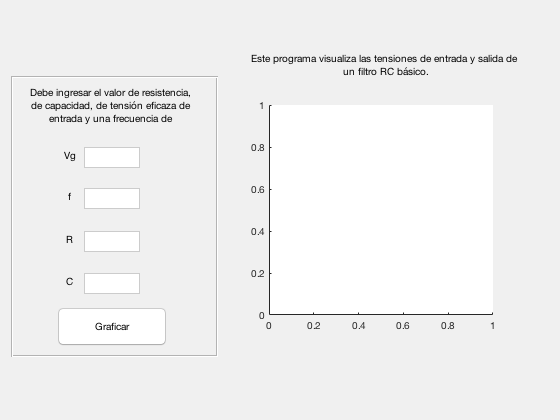

x = sym(1); 


XXX

# Propiedades

Las propiedades de Laplace sonarán conocidas, al ser ésta una generalización de la transformada de Fourier; sin embargo, la transformada de Fourier cuenta con dos propiedades que no tienen su correlato en el dominio de la transformada de Laplace; éstas son la propiedad de **dualidad** y el **teorema de Parseval**. 

**1. Linealidad:**

La transformada de Laplace es un operador lineal; esto quiere decir que si se tienen dos señales de tiempo continuo con transformada de Laplace:

Entonces, para cualquier par de escalares α y β se tiene:

**2. Desplazamiento por la derecha:**

Si se tiene una señal de tiempo continuo con transformada de Laplace:

Entonces, para cualquier número real positivo c:

**3. Escalamiento de tiempo:**

Si se tiene una señal de tiempo continuo con transformada de Laplace:

Entonces, para cualquier número real positivo a:

**4. Multiplicación por una potencia de t:**

Si se tiene una señal de tiempo continuo con transformada de Laplace:

Entonces, para cualquier entero positivo N:

**5. Multiplicación por una exponencial:**

Si se tiene una señal de tiempo continuo con transformada de Laplace:

Entonces para cualquier número real a:

**6. Multiplicación por una sinusoide:**

Si se tiene una señal de tiempo continuo con transformada de Laplace:

Entonces, multiplicando a la misma por una señal senoidal o cosenoidal se obtienen los siguientes pares:

Esto es fácilmente demostrable a partir de las notaciones de Euler del seno y del coseno. 

**7. Derivación en el dominio del tiempo:**

Si se tiene una señal de tiempo continuo con transformada de Laplace:

Entonces, la señal derivada de x(t) tiene la siguiente transformada de Laplace:

Donde x(o) es el **valor inicial** de x(t).  

La señal derivada segunda de x(t) tiene la siguiente transformada de Laplace:

**8. Integración:**

Si se tiene una señal de tiempo continuo con transformada de Laplace:

Entonces, 

**9. Convolución:**

Supóngase que se tienen dos señales de tiempo continuo con transformada de Laplace:

El producto en el tiempo corresponde a una convolución en el dominio s:

## Ejemplo 2

Supóngase que se tiene la señal de tiempo continuo causal pulso de tiempo c; la misma puede expresarse en términos del escalón unitario de la siguiente manera:

Al conocer la transformada del escalón unitario y hacer uso de las propiedades de linealidad y de desplazamiento, puede hallarse de forma inmediata la transformada de Laplace de x(t).

syms x t 

c = 1;

x = heaviside(t) - heaviside(t-c); 

XXX

## Ejemplo 3

La función rampa unitaria puede definirse de la siguiente manera:

Haciendo uso de la propiedad de multiplicación por una potencia de t, puede hallarse muy fácilmente su transformada de Laplace:

syms x t 

x = t*heaviside(t); 

XXX

## Ejemplo 4

Si se tiene una señal de tiempo continuo que resulta de la multiplicación del pulso de c segundos y una exponencial real: 

Es fácil, a partir del uso de la propiedad de la multiplicación por una exponencial, encontrar su transformada de Laplace; la transformada del pulso unitario de c segundos ya se ha tratado anteriormente. 

syms x c t a

assume(in(c, 'integer') & c >= 0)
assume(in(a, 'integer') & a >= 0)

x = (heaviside(t) - heaviside(t-c))*exp(a*t); 

XXX

## Ejemplo 5

Supóngase que se tiene una señal de tiempo continuo que es producto de la multiplicación de una señal cosenoidal con el escalón unitario:

Con el uso de la propiedad de la multiplicación por una señal sinusoidal, puede establecerse lo siguiente:

Al ya ser una transformada conocida la correspondiente al escalón unitario de tiempo continuo, se hace el reemplazo correspondiente. Se corrobora a continuación:

syms x w t a

assume(in(w, 'integer') & w >= 0)

x = cos(w*t)*heaviside(t); 

X = laplace(x)

# Transformada racional

En no pocas situaciones, la transformada de Laplace de una señal de tiempo continuo puede ser expresada con la división de dos polinomios de variable s:

El grado del polinomio del numerador es M, mientras que el del denominador es N. Definimos a las raíces de A(s) como los **polos** de la transformada de Laplace; la misma evaluada en los polos tiende a infinito.  

Los polos son números contenidos en el plano s; o sea que pueden ser tanto reales como complejos. En el caso de ser complejos siempre aparecen de a **pares conjugados**.  

El polinomio A(s) puede factorizarse para, de esa manera, presentar a X(s) como a continuación:

Esta última expresión puede desarrollarse en fracciones simples y, de esa manera, facilitar la obtención de la **transformada inversa** de Laplace. 

Se dice que si M < N, X(s) es **estrictamente propia**. 

Cuando los polos son **distintos**, la expansión en fracciones simples queda dada de la siguiente manera: 

Donde:

A estas constantes se las llama **residuos**.  

A partir de la expansión en fracciones simples, puede calcularse la transformada inversa de Laplace de los términos independientes y aplicar la propiedad de linealidad para obtener la señal en el dominio del tiempo:

% Numerador de la transformada racional.
num = [bm bmm1 bmm2 b1 b0]; 

% Denominador de la transformada racional.
den = [an anm1 anm2 a1 a0]; 

% Cálculo de residuos y polos. 
[r,p] = residue(num,den);

Puede existir el caso de tener **polos diferentes** con **dos o más complejos**. Bajo esta situación, la transformada de Laplace de la señal de tiempo continuo tendría el siguiente desarrollo por fracciones simples:

De nuevo, al utilizar las propiedades ya comentadas, puede obtenerse la señal en el dominio del tiempo:

Al desarrollar un poco los primeros dos términos de la sumatoria, la expresión de la señal en el dominio temporal queda de la siguiente manera:

Donde σ es la parte real del polo y ω la parte imaginaria. Es interesante destacar que aunque estén involucrados polos complejos, al ser conjugados, se compensan en la expresión de la señal en el dominio del tiempo para que la misma sea una función valuada en reales; esto último está demostrado en vistas de la ecuación obtenida que es la suma de una señal cosenoidal con exponenciales reales. 

## Ejemplo 6

Se tiene la siguiente transformada racional de Fourier:

Puede calcularse los polos y los residuos como se estableció más arriba; se harán a continuación de formas alternativas.

Para los polos:

Polos = roots([1 4 3 0])

Entonces, la transformada queda:

Son tres polos distintos; la expansión en fracciones simples de X(s) es, por lo tanto:

Entonces, desean calcularse los residuos.

Con el uso de esta fórmula, pueden hallarse fácilmente los coeficientes de la expansión:

c = zeros(1, length(Polos));
for i = 1:length(Polos)
   Pol = Polos;
   Pol(i) = [];
   den = Polos(i)*ones(1, length(Pol)) - Pol';
   c(i) = (Polos(i)+2)./(prod(den));
end
c

Con esta información, resulta inmediato el hallazgo de x(t):

# Relación entre la apariencia de una señal y sus polos

Supóngase que se tiene una señal de tiempo continuo con transformada racional de Laplace:

Por lo analizado anteriormente, puede inferirse que su "apariencia" en el dominio del tiempo va a estar directamente relacionada con la naturaleza de los polos que la misma tenga. 

- Si la misma cuenta con un polo p perteneciente a los reales, entonces la misma va a tener un término exponencial real en su expresión. 

- Si la misma cuenta con más de un polo real, entonces va a tener una cantidad igual a la cantidad de polos reales de términos exponenciales reales. 

- Si hay un par de polos complejos, va a existir un término cosenoidal multiplicado por una exponencial real en la expresión de la señal en el dominio del tiempo.

- Si hay más de un par de polos complejos, van a existir una cantidad igual de términos cosenoidales multiplicados por exponenciales reales en la expresión de la señal en el dominio del tiempo. 

% Un polo real
X = s/((s + j)*(s - j));
x = ilaplace(X);
ezplot(x,[0 10])
title('Dos polos complejos conjugados');
ezplot(x,[0 10])
title('Un polo real');
xlabel('t');
ylabel('x(t)');
% Par de polos complejos conjugados
X = s/((s + j)*(s - j));
x = ilaplace(X);
ezplot(x,[0 10])
title('Dos polos complejos conjugados');
xlabel('t');
ylabel('x(t)');
ylim([-4 4])

Se dice que **x(t) va a converger cuando t tienda a infinito** si y sólo si la parte real de cada uno de sus polos es menor a cero. T

# Transformadas con exponenciales

Pueden existir transformadas que tengan la siguiente expresión:

Donde se supone que los coeficientes h son distintos y reales. Y que los polinomios A y B tienen coeficientes reales.  

Esta expresión hace alusión a una función irracional o trascendental; es la transformada de funciones parcialmente continuas. 

Como se nota fácilmente, cada uno de los coeficientes de los términos exponenciales es un cociente de polinomios en s.  

Usando la propiedad de linealidad, la transformada inversa con la ayuda de la expansión en fracciones simples de cada cociente de polinomios y la propiedad de desplazamiento por la derecha puede obtenerse la expresión de la señal de tiempo continuo, que sería la siguiente:

## Ejemplo 7

Supóngase la siguiente transformada irracional de Laplace:

A partir del conocimiento del siguiente par de transformadas, puede hallarse de forma inmediata a la señal en el dominio del tiempo, con la propiedad de linealidad y desplazamiento temporal:

syms t s
X1 = (s+1)/(s^2+1);
X2 = (s+2)/(s^2+1);
x1 = ilaplace(X1)
x2 = ilaplace(X2)

¿Cuál será la señal de tiempo continuo asociada a X(s)?

# Transformada de ecuaciones diferenciales con entrada y salida

Se trabaja en el siguiente apartado, con sistemas LTI; éstos, pueden ser expresados con ecuaciones diferenciales que relacionan la entrada con la salida de los mismos. A partir de la transformada de Laplace se establecerá una relación de transferencia del sistema en el dominio s.

Las ecuaciones diferenciales pueden ser de distinto orden:

## 1er orden:

Las ecuaciones diferenciales de primer orden se expresan de la siguiente manera: 

Donde los coeficientes a y b corresponden a números reales.  

x(t) es la señal de entrada mientras que y(t) es la señal de salida.  

Al aplicar la transformada de Laplace a ambos lados del igual, se obtiene:

Puede despejarse la señal de salida en el dominio s, y establecer que las condiciones iniciales del sistema son nulas:

Y se llama** función transferencia** a:

Por lo tanto, la transferencia del sistema en el dominio s queda:

**La función transferencia caracteriza indefectiblemente el comportamiento de un sistema LTI.**

**Ejemplo 8: Circuito RC**

Veamos un ejemplo de aplicación práctica de la función transferencia.

El siguiente circuito es un **filtro pasa-bajos** pasivo de primer orden. 

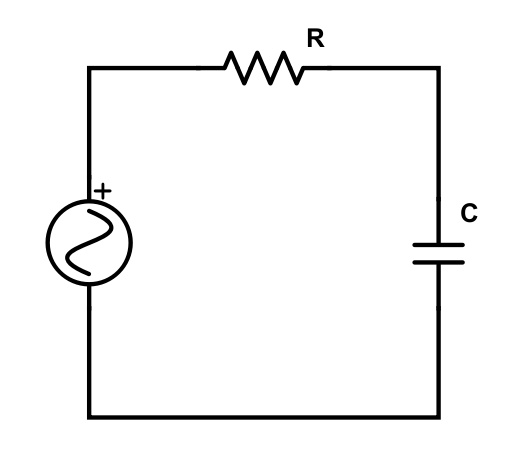

El mismo puede modelarse como un sistema LTI. Se establece que la entrada al sistema sea la tensión impuesta por el generador de tensión alterna y la salida la tensión en el capacitor. 

Ambas son señales senoidales con igual frecuencia pero con distinta amplitud y desfasadas entre sí.

En el siguiente ejemplo, se desea visualizar ambas formas de onda para hacer comparaciones sobre cómo es que varía la señal tensión para distintos valores de frecuencia.

Este sistema puede expresarse como una ecuación diferencial de primer orden; la deducción de la misma surge de plantear la ley de Kirchhoff.

Aplicando la transformada de Laplace a ambos lados, despejando la transformada de la señal de salida y estableciendo condiciones iniciales nulas se termina obteniendo la función de transferencia de este circuito RC.

El siguiente programita utiliza la matemática simbólica para trabajar con la función transferencia establecida y, a partir del uso de la misma, graficar la tensión de entrada (la del generador de tensión) y la función de salida (la tensión del capacitor).

circuitoRC_v2;
open circuitoRC_v2.m % Revisar la función local "transferencia". 

## 2do orden

Supóngase un sistema LTI caracterizado por la siguiente ecuación diferencial:

Supónganse nulas todas las condiciones iniciales.

Al aplicar el operador de Laplace a ambos lados del igual se obtiene:

Donde la función transferencia es:

## Ejemplo 9: sistema masa-resorte-amortiguador

El sistema masa-resorte-amortiguador es un sistema muy utilizado para modelar un sistema vibratorio. Una masa está conectada a una superficie a través de un resorte de **constante de rigidez K** y un amortiguador de **constante de amortiguamiento D**.

El sistema es excitado por una fuerza externa x(t) que produce que la masa M se desplace según lo establece y(t) que va a estar relacionada con la la primera.

Existen otras dos fuerzas que se oponen a este movimiento: la fuerza de resistencia ofrecida por el resorte y el amortiguamiento que disipa la energía mecánica en energía térmica en forma de calor.

La segunda ley de Newton establece que la sumatoria de las fuerzas en el cuerpo es igual a su masa multiplicada por su aceleración:

A partir de esta ecuación de segundo orden de entrada y salida es sencillo hallar la función transferencia del sistema:

Esta función caracteriza al sistema y permite hallar la relación entre la señal de entrada y su respuesta.

**Aconsejamos al alumno a llevar a cabo un programa similar al del circuito RC que permita visualizar el moviemiento de la masa M en función de la fuerza que se le impone. **

## Referencias

- Kamen, Edward W., and Bonnie S. Heck. ***Fundamentos de señales y sistemas usando la Web y Matlab***. Pearson Prentice-Hall, 2008.

- Oppenheim, Alan V.; Willsky, Alan S.; Nawab, S. Hamid. ***Señales y sistemas***. Pearson Educación, 1998.